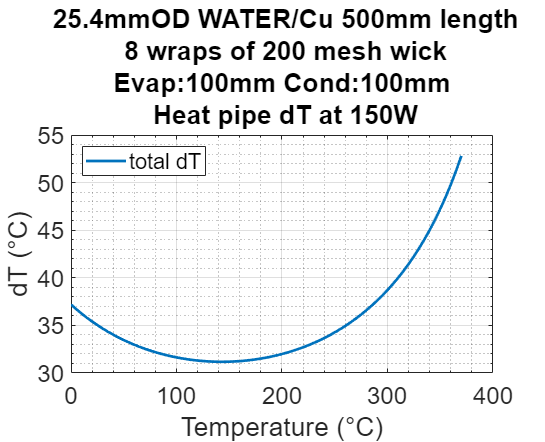

%%%%%%%%%%%%%%%%%%%% Graph 12: dT at operting power

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%% Create Figure 12: Heat Pipe dT %%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure12 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

% Create axes
axes1 = axes('Parent',figure12);
hold(axes1,'on');

plot1 = plot(T(:,1),dT_tot_2,'Parent',axes1);
set(plot1(1),'DisplayName','total dT','LineWidth',2);
%set(plot1(2),'DisplayName','total dT2');

ylabel({'dT (°C)'});                                % Create ylabel
xlabel({'Temperature (°C)'});                              % Create xlabel

Cap_name1 = strcat({' '},string(do_mm),'mmOD',{' '},string(NAME_FLUID),'/',string(NAME_METAL),{' '},string(l_mm),'mm length');
if WICK_TYPE == 'mesh'
    Cap_name2 = strcat({' '},string(NW),{' '},'wraps',{' '},'of',{' '},string(MESH_NUMBER),{' '},string(WICK_TYPE),{' '},'wick');
else
    Cap_name2 = strcat({' '},'With',{' '},string(WICK_TYPE),{' '},'wick');
end
Cap_name3 = strcat('Evap:',string(EVAP_Length),'mm',{' '},'Cond:',string(COND_Length),'mm');
Cap_name4 = strcat(' Heat pipe dT at',{' '},string(OPRATING_POWER),'W');

title({Cap_name1,Cap_name2,Cap_name3,Cap_name4});

%xlim(axes1,[min(P_range) max(P_range)]);            % X-limits of the axes
%ylim(axes1,[0 max(T)]);                         % Y-limits of the axes
box(axes1,'on');
set(axes1,'XMinorTick','on','YMinorTick','on')      % Set the remaining axes properties

% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','northwest');

set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')